# Tutorial03 Random Walks

#### Notes

Overview

In this lab, we will:

- generate a # of 2D random walks

- Plot a few such trajectories

- Take a look at the distribution of a large # of random walkers.

Goal

For us to get an intuitive feeling of what a random walk actually looks like.

Definition

**Random walk**. A mathematical formulation. The "movements of an object or changes in a variable that follow no discernible pattern or trend."

Another source: "n. Statistics. A sequence of changes, either in the value of a **random** variable or in a process (as in the price of a share of stock), in which the direction and size of each change is randomly determined, subject to some specified rules."

Without further ado, let's go!

1 Useful Matlab Commands

a1 = [1, 2, 3]

a1 =      1     2     3


b1 = [1; 2; 3]

b1 =      1
     2
     3


c1 = [1, 2, 3]'

c1 =      1
     2
     3


d1 = [1, 2, 3; 4, 5, 6]

d1 =      1     2     3
     4     5     6


Recap.

- The [] lets us specify a list or array.

- ' is for transpose.

x = 1+2

x = 3

disp('message')

message


disp(num2str(x))

3


disp(['The value of x= ', num2str(x, 10), '.'])

The value of x= 3.


**disp** is like printf in C or print in Python.

The [] bundles the three items into a single string of characters.

We can use the same trick to title a graph.

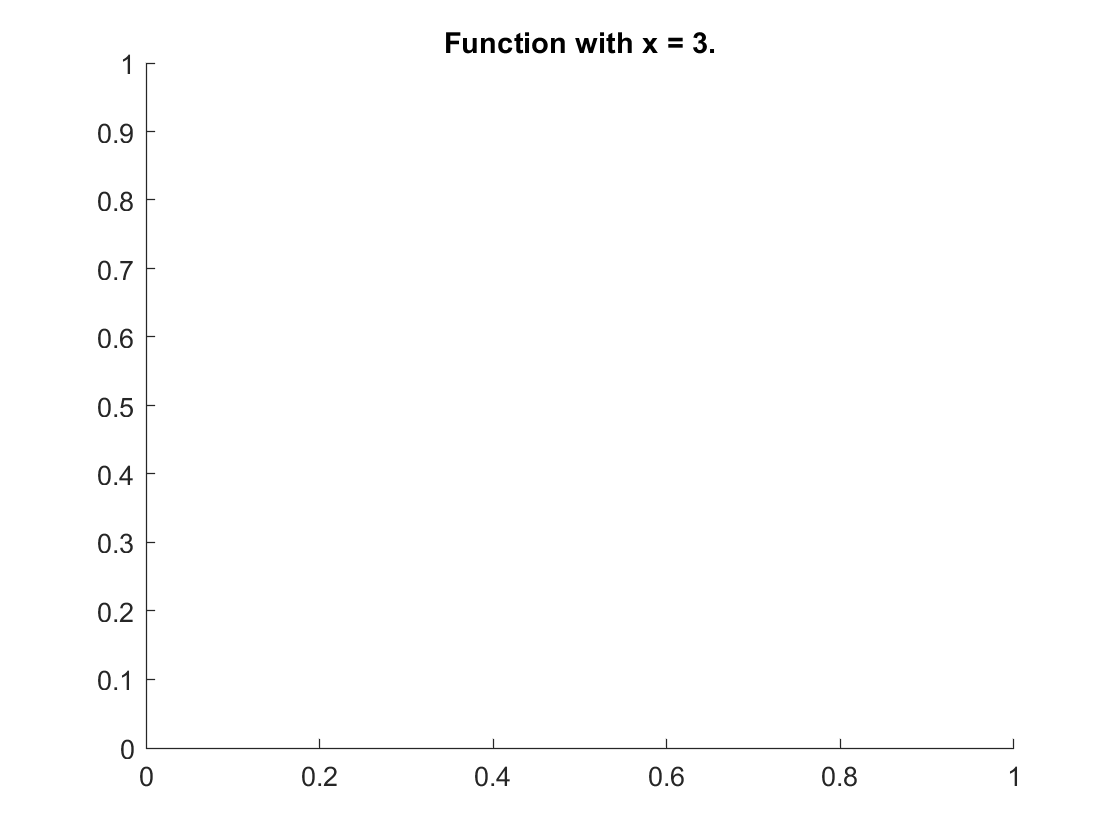

title(['Function with x = ', num2str(x, 10), '.'])

Note: num2str has an optional second arg, the # of sig digs to show.

Some functions

**rand**: generate a uniformly distributed rand # btw 0 and 1. rand(1, n) generates n such #s. rand(3,7) generates a 3 x 7 array.

rand(1,3);
rand(3,8);

**semilogy**: plot with log base 10 y-axis.

**for** **loop**: 

-----------

for i = 1:1000

    [list of commands]

end

-----------

Recap: **end** closes the scope of the **for**.

**i** is the **control variable**.

We can also make nested for loops.

CAUTION: we can use the value of i inside the loop, but BETTER NOT TO change the value of i.

-----------

for i = 1:1000

for j = 1:10

    [list of commands] % this will be executed 10,000 times

end end

-----------

a = 3, b = 2

a = 3

b = 2

a > b

ans = logical
   1


a < b

ans = logical
   0


% a = b
a == b %#ok<EQEFF> 

ans = logical
   0


a == 3 %#ok<EQEFF> 

ans = logical
   1



if a > b
    display([num2str(a), 'is bigger than ', num2str(b)])
elseif a == b
    display(['a and b are equal. They are both ', num2str(a)])
else
    display([num2str(b), 'is bigger than ', num2str(a)])
end

3is bigger than 2


-----------

The **break** command. Prematurely terminates a loop and goes immediatemly to the command after the loop. (c.f. **disp** command in this case).

% a = 3  % this line will make the loop run 1000 times.
n = 1000

n = 1000

for i = 1:n
  disp(i)
  if a > b
      break
  end % this closes the "if"
end

     1



disp('done')

done


-----------

**Histogram**

hist(v,n)

v = [1 2 3 4 5 6 7 8 9]

v =      1     2     3     4     5     6     7     8     9


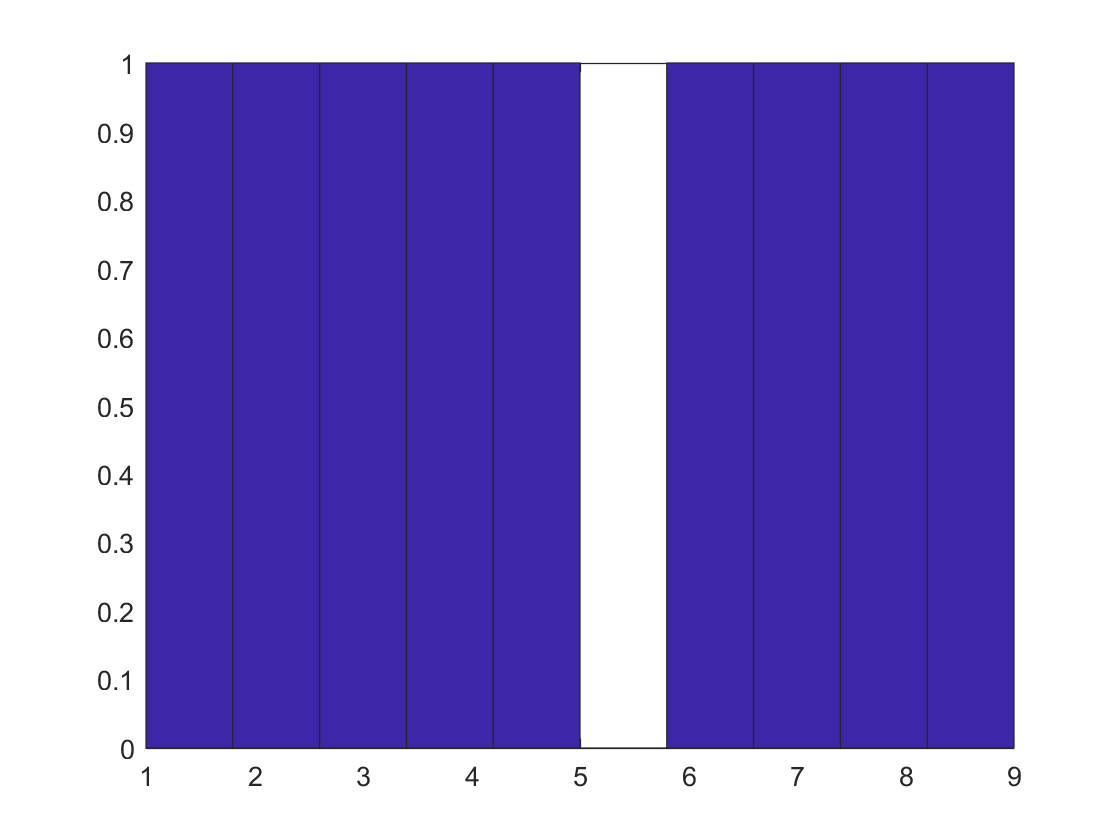

hist(v, 10)

Produces a histogram of the values contained in the vector **v** with 3 bins.

If we just do **hist(v)**, it would try to guess the # of bins <- not always successful.

For more information,

% help hist

-----------

set(gca, 'FontSize', xx)

After making a plot, the above command will change the font size on the axes to xx.

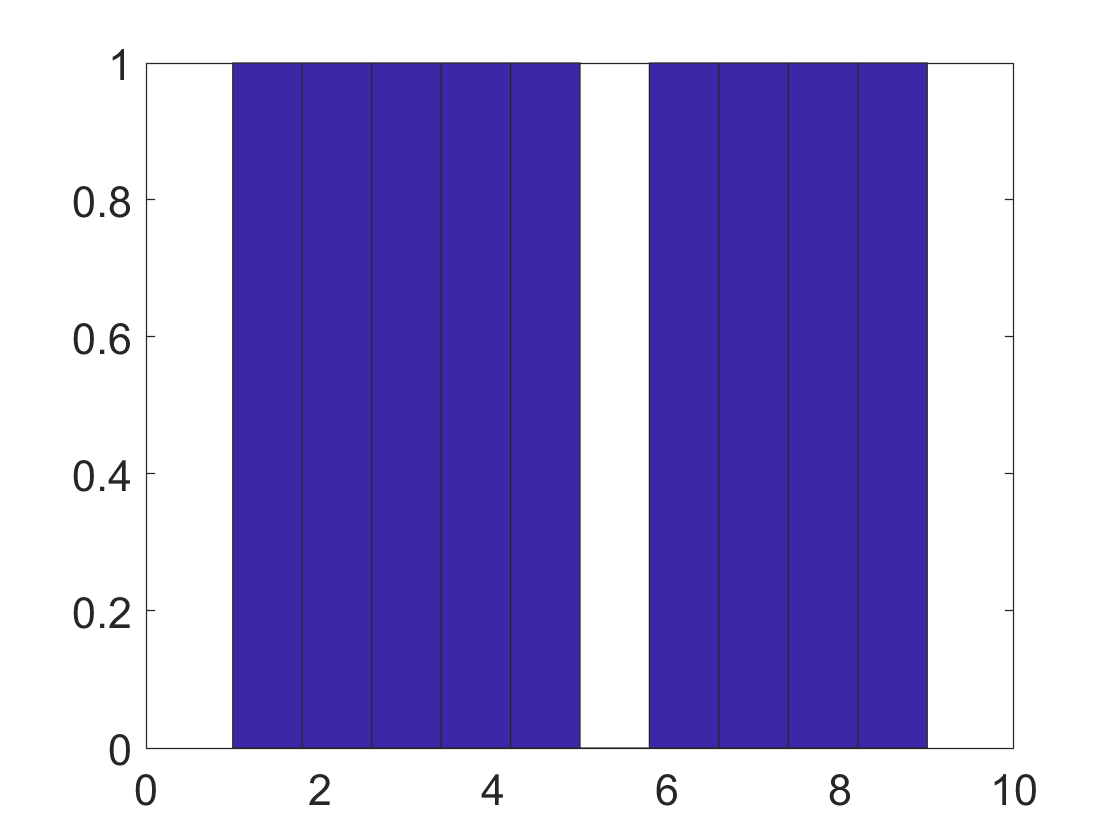

set(gca, 'FontSize', 16)

The var **gca** is MATLAB's way of denoting the most recently drawn graph.

2. Random Walks

2.1 Goals